## GLM Modeling of the Clustered Multielectrode Data taken with Sparse Noise Stimulus

Add project source code to the path

clear all
project_root_dir = '.';
addpath(genpath(fullfile(project_root_dir, 'src')));

### ============= Load Data =============

Import and recreate the sparse noise stimulus

config_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cbsn5x6.m';
configs = Config(config_file_path);
sn_stim = SparseNoiseStimulus(configs.config);

Import the timestamps for when the stimulus happened

crs_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\processed\Cbsn5x6.ch4.crs';
stim_ts = StimTimeStamps(crs_file_path, configs.config);

WARNING!! deltimes between records in getcrs have variance >1%


Import Corresponding Spike Event Timing Data

event_timing_file_path = 'Z:\LabMembers\Jong\Interneuron_multie\190417C\SN\Cbsn5x6_clu12.txt';
spike_times = SpikeTimes(event_timing_file_path);

Compute some basic statistics on the data

dtStim = (stim_ts.tempresolu); % time bin size for stimulus (s)
RefreshRate = 1/dtStim; % Refresh rate of the monitor
nT = size(sn_stim.stimulus, 3); % number of time bins in stimulus
nsp = length(spike_times.spike_t_vector); % number of spikes
  
% Print out some basic info
fprintf('--------------------------\n');

--------------------------


fprintf('Number of stim frames: %d  (%.1f minutes)\n', nT, nT*dtStim/60);

Number of stim frames: 8192  (3.9 minutes)


fprintf('Time bin size: %.1f ms\n', dtStim*1000);

Time bin size: 28.6 ms


fprintf('Number of spikes: %d (mean rate=%.1f Hz)\n\n', nsp, nsp/nT*RefreshRate);

Number of spikes: 659 (mean rate=2.8 Hz)



### **============= Preprocessing Data for the Model ============**

Let's bin the spike train with the stimulus timestamps.

[tbin_centers, binned_spikes] = hist_bin_spikes(stim_ts, spike_times); %compute binned spike train

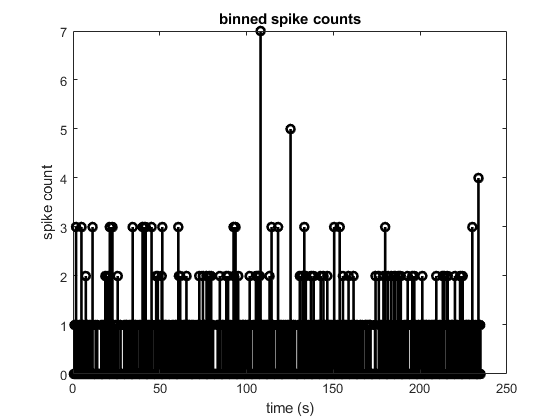

% Visualize the binned spike train
figure;
stem(tbin_centers,binned_spikes, 'k', 'linewidth', 2);
title('binned spike counts');
ylabel('spike count'); xlabel('time (s)');

Create Design Matrix

rf_temporal_len = 25; % frames
Xdsgn = make_design_matrix(sn_stim, rf_temporal_len);

dataset = DataSet(Xdsgn, binned_spikes);
train_data_pct = 0.7;
[train_var, train_lab, test_var, test_lab] = dataset.divide_train_test_data(train_data_pct);

### **=================  Plot STA  ================**

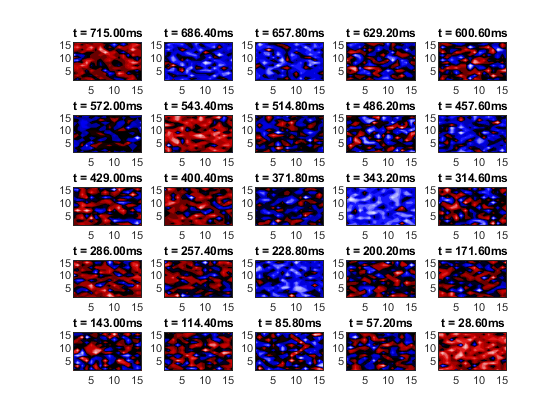

% It's extremely easy to compute the STA now that we have the design matrix
sta = (Xdsgn'*binned_spikes)/nsp;
sta = reshape(sta, [configs.config.gridsize, configs.config.gridsize, rf_temporal_len]);
plot_sta(sta, rf_temporal_len, stim_ts.tempresolu);

### **=================  Fit GLM  ================**

pGLMwts = glmfit(Xdsgn, binned_spikes, 'poisson','constant', 'on');

% plot whitened sta (weights from glm)
sta_glm = reshape(pGLMwts(2:end), [configs.config.gridsize,configs.config.gridsize,rf_temporal_len]);

The end operator must be used within an array index expression.

plot_sta(sta_glm, rf_temporal_len, stim_ts.tempresolu);